# Linear Control Design II - Group Work Problem Module 19 Solution

## **Part A - **Time Dependent Discrete LQR Control: first order system.

The purpose of this exercise is to illustrate in detail what how a time dependent optimal controller is designed for a simple first order system. Consider a discrete time controller for a system given by:


$$x(k+1)=0.3679 \: x(k) + 0.6321 \: u(k)$$


with the boundary condition that $x(0)=1$. For this system find an optimal controller to minimizes the performance index:


$$J = \frac{1}{2}\left[ x(10)^2 \right] + \frac{1}{2} \sum\limits_{k=0}^{9}\left[ x^2(k) + u^2(k) \right]$$


Note that in this example the weighting matrices have been selected to be:


$$\mathbf{S}=1 \qquad \mathbf{R_1}=1 \qquad \mathbf{R_2}=1$$


The minimum value of the index $J$ is also to be determined.

To solve this problem it is required that it be solved backwards from the final time. The boundary condition on the matrix $\mathbf{P}(N)$is:


$$\mathbf{P}(N) = \mathbf{S} \Rightarrow \mathbf{P}(N) = \mathbf{P}(10)=\mathbf{S}=1$$


The Riccati equation has to be solved in order to calculate the time varying optimal gain. In this case it can be written as:


$$\mathbf{P}(k) = 1+0.3679 \cdot \mathbf{P}(k+1)\left[ 1+0.6321 \cdot 1 \cdot 0.6321 \cdot \mathbf{P}(k+1) \right]^{-1}0.3679$$


which can be simplified to:


$$\mathbf{P}(k) = 1+0.1354 \cdot \mathbf{P}(k+1)\left[ 1+0.3996 \cdot \mathbf{P}(k+1) \right]^{-1}$$


One can now calculate backwards to the desired start time:

 
$$\mathbf{P}(9) = 1+0.1354 \cdot 1 \cdot \left[ 1+0.3996\cdot 1 \right]^{-1} = 1.0967\\ \mathbf{P}(8) = \ldots$$


**Problem 1 **Write a Matlab program to carry though these calculations to find $\mathbf{P}(0)$. What is especially noticeable about the values of $\mathbf{P}(k)$ during this process? What is the steady state value of $\mathbf{P}(k)$ i.e. $\mathbf{P}_{SS}$? Note that this value must be positive as $\mathbf{P}(k)$must be positive definite.

Calculate now the feedback gains necessary (at the different sampling times) to accomplish the desired control.

**Solution:**

We can find the values of $\mathbf P(k)$ by running the recursion


$$\mathbf P(k-1) = 1 + 0.1354\cdot\mathbf P(k)[1 + 0.3996\cdot\mathbf P(k)]^{-1}$$


with the boundary condition $\mathbf P(10) = \mathbf S = 1$

Matlab program to carry though the calculations to find $\mathbf{P}(k)$ $\forall k \in [1..10]$:

% Make row-vector with the elements P(k) (k=[10..1]).
S = 1;
P(11) = S;
for i=10:-1:1
    P(i) = 1 + 0.1354*P(i+1)*(1 + 0.3996*P(i+1))^(-1);
end
P

P =     1.1037    1.1037    1.1037    1.1037    1.1037    1.1037    1.1037    1.1037    1.1032    1.0967    1.0000

We note that $\mathbf P(8)< \mathbf P(9) < \mathbf P(10)$ etc. (This actually holds all the way down to $k=0$, but the change in $\mathbf P$ is insignificant).

We can find the steady state value of $\mathbf P(k)$, $\mathbf P_{SS}$ either by solving the equation:


$$\mathbf P_{SS} = 1 + 0.1354\cdot\mathbf P_{SS}[1 + 0.3996\cdot\mathbf P_{SS}]^{-1}, \qquad \mathbf P_{SS}> 0$$


Or we can simply note that the value of $\mathbf P(0)$and $\mathbf P(1)$ are equal to within $5$ decimals. Thus


$$\mathbf P_{SS} = 1.1037$$


% Steady state solution (you can choose any of the first seven values)
Pss = P(1);    
disp('The steady state value of the Riccati equation is:'); disp([' Pss = ' num2str(Pss)]);

The steady state value of the Riccati equation is:
 Pss = 1.1037


**Problem 2 **The optimal control law is:


$$u(k) = -\mathbf{K}(k)x(k)$$


Use this law to calculate the states $x(1), x(2), x(3), \ldots , x(9)$. What is the sequence of inputs necessary to give this state response?

**Solution:**

The optimal control law is:


$$u(k) = -\mathbf K(k) x(k)$$


from the book Eq. (5.116) page 331 we have:


$$\mathbf K(k) = (\mathbf R_2+\mathbf G^{T} \mathbf P(k) \mathbf G)^{-1} \mathbf G^{T} \mathbf P(k) \mathbf F$$


where $\mathbf G = 0.6321$ and $\mathbf F = 0.3679$

Using the initial condition $x(0) = 1$and knowing that $x(k+1) = \mathbf F x(k) + \mathbf  G u(k)$, we can calculate the input and state sequences:

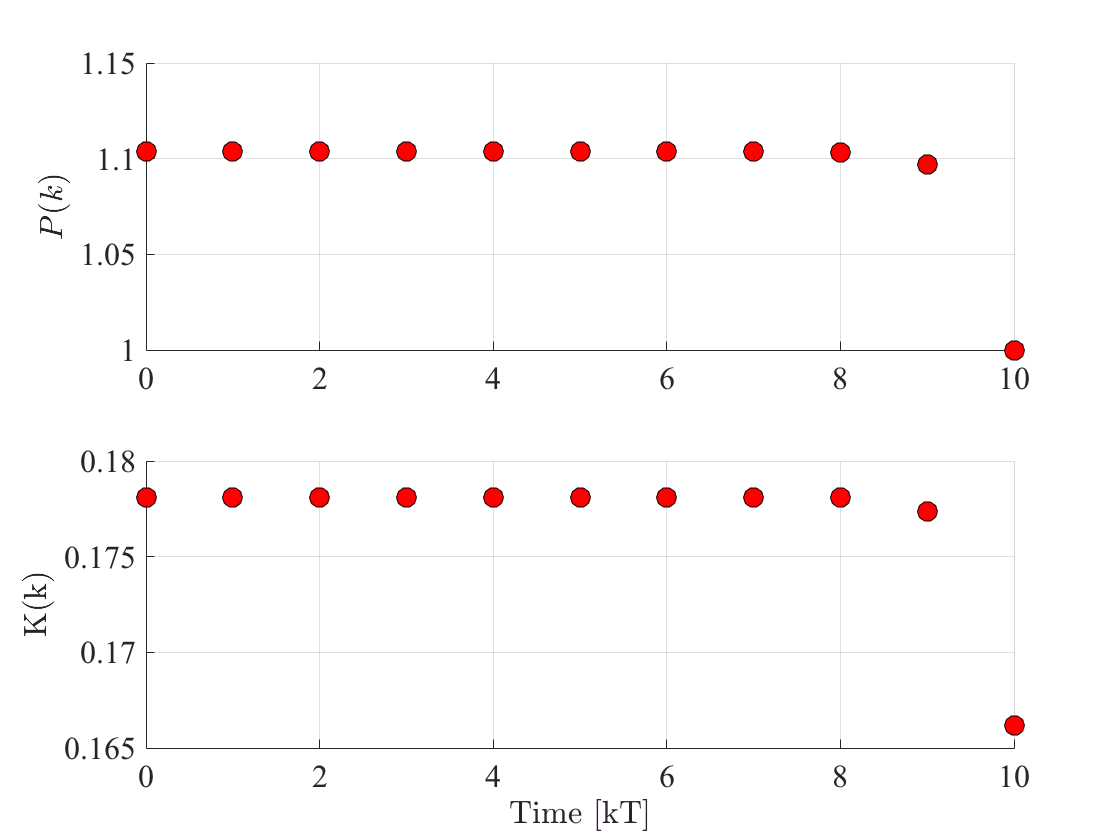

F = 0.3679;
G = 0.6321;
R1 = 1;
R2 = 1;

% calculate values for u(k) and x(k), note that k=i-1:
x(1) = 1; % initial condition x(0) = 1
for i=1:10,
    K(i) = (R2+G'*P(i)*G)^(-1)*G'*P(i)*F; % Eq. (5.116) page 331
    u(i) = -K(i)*x(i); % Eq. (5.115) page 331
    x(i+1) = F*x(i) + G*u(i); % Time increment
end
i = 11;
K(i) = (R2+G'*P(i)*G)^(-1)*G'*P(i)*F; % Eq. (5.116) page 331
u(i) = -K(i)*x(i);

%Plotting
figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
i = 0:10; 
% v = [0 9 1 1.2]; axis(v);
plot(i,P,'o','MarkerEdgeColor','k','MarkerFaceColor','r','MarkerSize',10)
ylabel('$P(k)$','FontName','times','FontSize',16,'Interpreter','latex');

h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
% v = [0 9 0 0.2]; axis(v);
plot(i,K,'o','MarkerEdgeColor','k','MarkerFaceColor','r','MarkerSize',10)
ylabel('K(k)','FontName','times','FontSize',16,'Interpreter','latex');
xlabel('Time [kT]','FontName','times','FontSize',16,'Interpreter','latex')

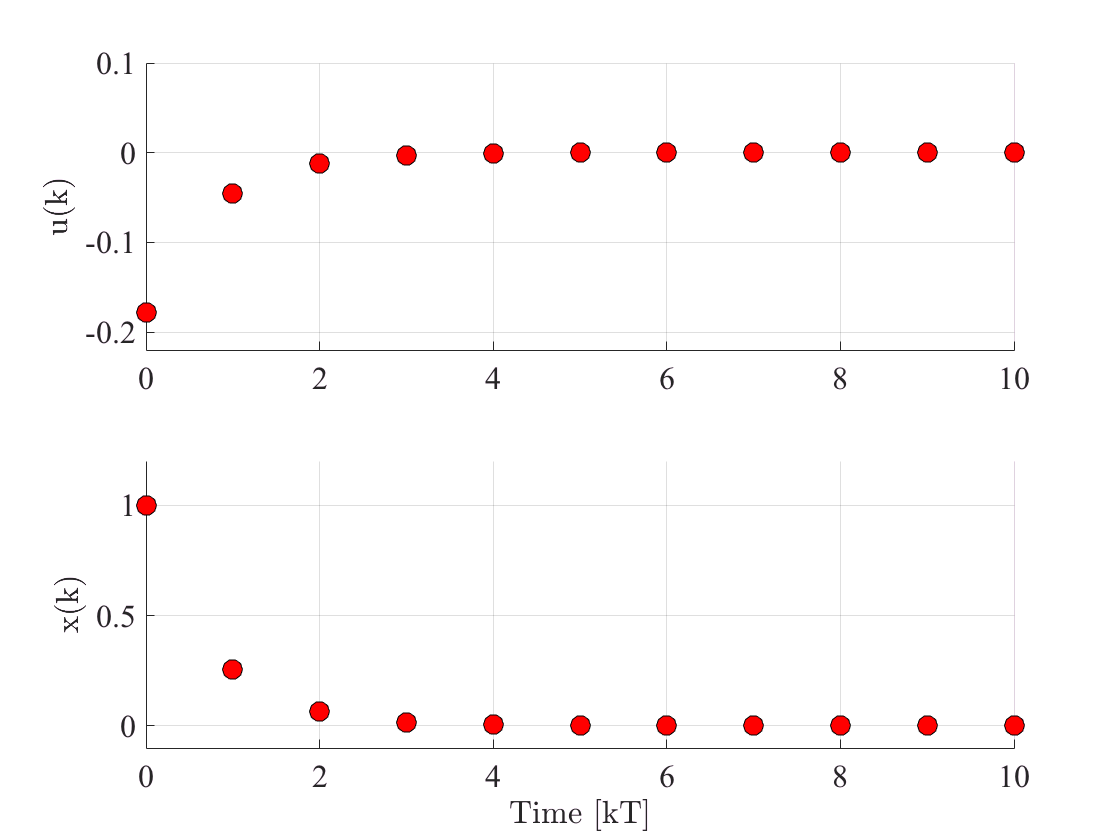


figure, h3 = subplot(2,1,1); set(h3,'FontName','times','FontSize',16)
hold on, grid on
v = [0 10 -0.22 0.1]; axis(v);
plot(i,u,'o','MarkerEdgeColor','k','MarkerFaceColor','r','MarkerSize',10)
ylabel('u(k)','FontName','times','FontSize',16,'Interpreter','latex');

h4 = subplot(2,1,2); set(h4,'FontName','times','FontSize',16)
hold on, grid on
v = [0 10 -0.1 1.2]; axis(v);
plot(i,x,'o','MarkerEdgeColor','k','MarkerFaceColor','r','MarkerSize',10)
ylabel('x(k)','FontName','times','FontSize',16,'Interpreter','latex');
xlabel('Time [kT]','FontName','times','FontSize',16,'Interpreter','latex')

**Problem 3 **What is the minimum value of the performance index $J_{\min}=\frac{1}{2}x^\text{T}(0)\mathbf{P}(0)x(0)$ ?

**Solution:**

We can either calculate the minimum value of the performance index by computing $J_{min} = \frac{1}{2} x(10)^2 + \sum_{k=0}^9[x(k)^2 + u(k)^2]$

as we know the optimal $u(k)$ and resulting $x(k)$, or we can simply calculate $J_{min} = \frac{1}{2} x(0)^T \mathbf P(0) x(0):$

Jmin = 0.5*x(1)'*P(1)*x(1);
disp('The minimum value of the performance index is'); disp(Jmin);

The minimum value of the performance index is
    0.5519


## **Part B - **An integral LQR Regulator for a Servo System.

It is desired to design a steady state optimal controller for the servo loop in the Figure below:

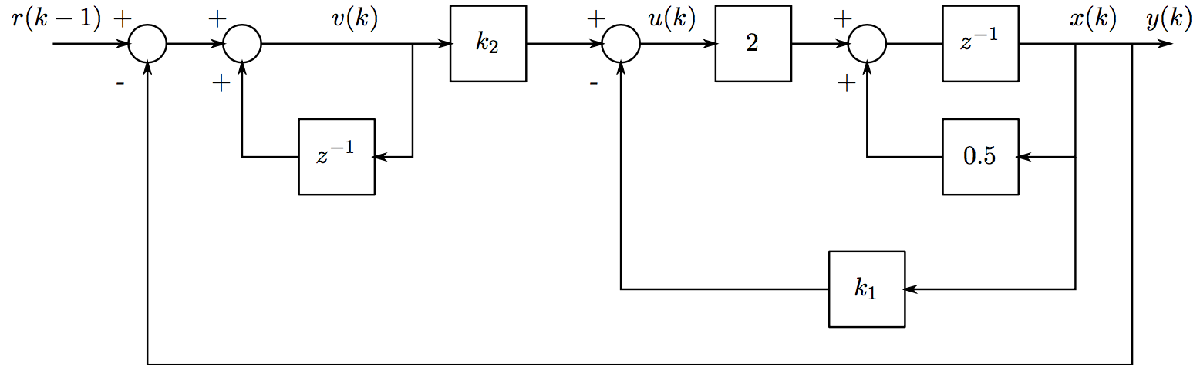

The sample period for the loop is $T=0.1 \mathrm{s}$. Clearly, $k_1$ is the integral gain and $k_2$ is the proportional gain.

**Problem 1**  Write down the state equations of the system, including the inputs and states. Show that the state equations of the system are:


$$\left[\matrix{ x(k+1) \cr v(k+1)}\right] = \left[\matrix{0.5 & 0 \cr -0.5 & 1}\right] \left[\matrix{ x(k) \cr v(k) }\right] + \left[\matrix{ 2 \cr -2}\right]u(k) + \left[\matrix{ 0 \cr 1 }\right] r(k)$$


**Solution:**

We are interested in the state equations of the open loop system, so ignore $k_1$, $k_2$ for the time being.

We read of the state equations from the block diagram:


$$x(k+1) = 2 u(k) + 0.5 x(k) \\ v(k) \quad\ =  v(k-1) + r(k-1) - y(k) = v(k-1) + r(k-1) - x(k)$$


note that the time index of $v$ does not mach that of $x$, so we time shift and get:


$$x(k+1) = 2 u(k) + 0.5 x(k) \\ v(k+1) = v(k) + r(k) - x(k+1) =  v(k) + r(k) - 2 u(k) - 0.5 x(k)$$


in matrix form this is:


$$\left[\matrix{ x(k+1) \cr v(k+1)}\right] = \left[\matrix{0.5 & 0 \cr -0.5 & 1}\right] \left[\matrix{ x(k) \cr v(k) }\right] + \left[\matrix{ 2 \cr -2}\right]u(k) + \left[\matrix{ 0 \cr 1 }\right] r(k)$$


**Problem 2**  Write down the state equations for the system when $t\rightarrow \infty$. The reference input is to be held constant.

**Solution:**

Assuming that we find an input $u(k)$ that can stabilise the system, as $k\rightarrow \infty$ the system will reach the steady state:


$$\left[\matrix{ x(\infty) \cr v(\infty) }\right] = \left[\matrix{ 0.5 & 0 \cr -0.5 & 1 }\right] \left[\matrix{ x(\infty) \cr v(\infty) }\right] + \left[\matrix{ 2 \cr -2 }\right] u(\infty) + \left[\matrix{ 0 \cr 1 }\right] r$$


By solving for $x(\infty)$ and $u(\infty)$ we get:


$$x(\infty) = r, \qquad u(\infty) = \frac{r}{4}$$


Note that we do not have any information about $v(\infty)$. This makes sense. 

While $v(k+1) - v(k) \rightarrow -0.5x(\infty) -2u(\infty) = 0$ as $k\rightarrow \infty$ the value $v(\infty)$ is dependant on the starting conditions of $x$ and $v$.

**Problem 3**  Define the new incremental variables:


$$x_e(k) = x(k) - x(\infty) \\ v_e(k) = v(k) - v(\infty) \\ u_e(k) = u(k) - u(\infty)$$


Now write down the state equations of the system in terms of the new variables above. What is the new feedback law?

**Solution:**

We define new variables:


$$x_e(k) = x(k) - x(\infty) \\ v_e(k) = v(k) - v(\infty) \\ u_e(k) = u(k) - u(\infty)$$


Note that $x_e$ becomes the difference between the state and the reference.


$$\left[\matrix{ x_e(k+1) \cr v_e(k+1) }\right] = \left[\matrix{ x(k+1) \cr v(k+1) }\right] - \left[\matrix{ x(\infty) \cr v(\infty) }\right] \\ \qquad \qquad \;\ = \left[\matrix{0.5 & 0 \cr -0.5 & 1}\right] \left[\matrix{x(k) \cr v(k)}\right] + \left[\matrix{ 2 \cr -2 }\right] u(k) + \left[\matrix{ 0 \cr 1 }\right] r(k) - \left[\matrix{ x(\infty) \cr v(\infty) }\right] \\ \qquad \qquad \;\ = \left[\matrix{0.5 & 0 \cr -0.5 & 1}\right] \left[\matrix{x_e(k) + x(\infty) \cr v_e(k) + v(\infty)}\right] + \left[\matrix{ 2 \cr -2 }\right] [u_e(k) + u(\infty)] + \left[\matrix{ 0 \cr 1}\right] r(k) -\left[\matrix{x(\infty) \cr v(\infty)}\right] \\ \qquad \qquad \;\ = \left[\matrix{ 0.5 & 0 \cr -0.5 & 1 }\right] \left[\matrix{ x_e(k) \cr v_e(k) }\right] + \left[\matrix{ 2 \cr -2 }\right] u_e(k) + \left[\matrix{0 \cr 1}\right] r(k) + \left[\matrix{ -0.5 \cr -0.5 }\right] x(\infty) + \left[\matrix{ 2 \cr -2 }\right] u(\infty) \\ \qquad \qquad \;\ = \left[\matrix{ 0.5 & 0 \cr -0.5 & 1 }\right] \left[\matrix{ x_e(k) \cr v_e(k) }\right] + \left[\matrix{ 2 \cr -2 }\right] u_e(k) + \left[\matrix{ 0 \cr 1 }\right] r(k) + \left[\matrix{ -0.5 \cr -0.5 }\right] r + \left[\matrix{ 0.5 \cr -0.5}\right] r \\ \qquad \qquad \;\ = \left[\matrix{ 0.5 & 0 \cr -0.5 & 1 }\right] \left[\matrix{ x_e(k) \cr v_e(k) }\right] + \left[\matrix{ 2 \cr -2 }\right] u_e(k) + \left[\matrix{ 0 \cr 1 }\right] r(k) + \left[\matrix{0 \cr -1}\right] r$$


By holding $r(k)$ constant the reference disappears completely from the incremental system.

The control law for the incremental system is:


$$\qquad\quad\; u(k) = k_2 v(k) - k_1 x(k) \\ u_e(k) + u(\infty) = k_2 v_e(k) + k_2 v(\infty) - k_1 x_e(k) - k_1 x(\infty) \\ \qquad\quad u_e(k)  = k_2 v_e(k) + k_2 v(\infty) - k_1 x_e(k) - k_1 x(\infty) -u(\infty) \\ \qquad\qquad\ \ =  k_2 v_e(k)  - k_1 x_e(k) + k_2 v(\infty) - k_1 x(\infty) - u(\infty) \\ \qquad\qquad\ \ =  k_2 v_e(k)  - k_1 x_e(k) + k_2 \frac{u(\infty) + k_1x(\infty)}{k_2} - k_1 x(\infty) - u(\infty) \\ \qquad\qquad\ \ =  k_2 v_e(k)  - k_1 x_e(k)  \\ \qquad\qquad\ \ = -\mathbf K \left[\matrix{ x_e(k) \cr v_e(k) }\right] =-\left[\matrix{ k_1 &-k_2}\right] \left[\matrix{x_e(k) \cr v_e(k) }\right]$$


**Problem 4**  Design a optimal steady state controller for the system above such that the performance index:


$$J = \frac{1}{2}\sum\limits_{k=0}^\infty \left[\left[\matrix{ x_e(k) \cr v_e(k) }\right]^\text{T} \mathbf{R}_1 \left[\matrix{ x_e(k) \cr v_e(k) }\right] + u_e^\text{T}(k) \mathbf{R}_2 u_e(k)\right]$$


is minimized where:


$$\mathbf{R}_1 = \left[\matrix{100 & 0 \cr 0 & 1}\right], \qquad \mathbf{R_2}=1$$


Find the optimal feedback gain matrix for the servo system.

**Solution:**

We can find the controller that minimises the given performance index by solving the discrete time Riccati Equation:


$$\mathbf P =\mathbf R_1 +\mathbf F^T\mathbf P\mathbf F -\mathbf F^T\mathbf  P\mathbf G [(\mathbf R_2 + \mathbf G^T \mathbf P \mathbf G)^{-1}] \mathbf G^T \mathbf P \mathbf F \\ \mathbf K = (\mathbf R_2 + \mathbf G^T \mathbf P \mathbf G)^{-1} \mathbf G^T \mathbf P \mathbf F$$


Note that this controller penalizes deviation between output and reference, and deviation form the steady state value of $u$.

The controller gain can be found through iteration, or with Matlab's `dlqr` or `dare` functions.

% Define System
F = [0.5 0 ; -0.5 1];
G = [2; -2];
Gr = [0; 1];
C = [1 0];
D = 0;

% Define Weights
R1 = [100 0 ; 0 1];
R2 = 1;

% Use the dlqr package to compute the controller gains K and the infinite horizon ricatti solution P
[K,P,~] = dlqr(F, G, R1, R2)

K =     0.2494   -0.0475

P =   100.0624   -0.0119
   -0.0119   10.5168

% Use the dare to compute the controller gains K and the infinite horizon ricatti solution P
P = dare(F,G,R1,R2);
K = inv(R2 + G'*P*G)*G'*P*F;
K,P

K =     0.2494   -0.0475

P =   100.0624   -0.0119
   -0.0119   10.5168

% Use iteration to determine the controller gains K and the infinite horizon ricatti solution P

% Iterate forward to a solution in the first case
% Start with the solution of the SS Riccati Equation with P = [0 0;0 0].
P = [0 0;0 0];
P = R1 + F'*P*F - F'*P*G*((R2 + G'*P*G)^-1)*G'*P*F; % Eq. (5.114) page 331

% Iterate for many steps and check whether or not P is constant.
for i = 1:1000
   P = R1 + F'*P*F - F'*P*G*((R2 + G'*P*G)^-1)*G'*P*F; % Eq. (5.114) page 331
end
disp('Solution of the Riccati equation:'); disp(P);

Solution of the Riccati equation:
  100.0624   -0.0119
   -0.0119   10.5168



K = inv(R2 + G'*P*G)*G'*P*F; % Eq. (5.116) page 331
disp('Optimal controller K:'); disp(K);

Optimal controller K:
    0.2494   -0.0475


In any case the values of $\mathbf P$ and $\mathbf K$ are:


$$\mathbf P = \left[\matrix{ 100.0624  &  -0.0119 \cr -0.0119  & 10.5168 }\right], \qquad \mathbf K = \left[\matrix{0.2494 & -0.0475}\right]$$


or in terms of $k_1$, $k_2$:


$$k_1 = 0.2494 \\ k_2 = 0.0475$$


**Problem 5**  Simulate the servo control system response to a step change in the reference input. Plot the input to the system on one plot and in two different plots below, the output of the integrator $v(k)$ and the system output $y(k)$. Explain your results.

**Solution:**

In the MatLab code below, a simulation of the closed loop system with a constant reference is performed. Note how the steady state error is $0$, i.e. after a while the system reaches the reference.

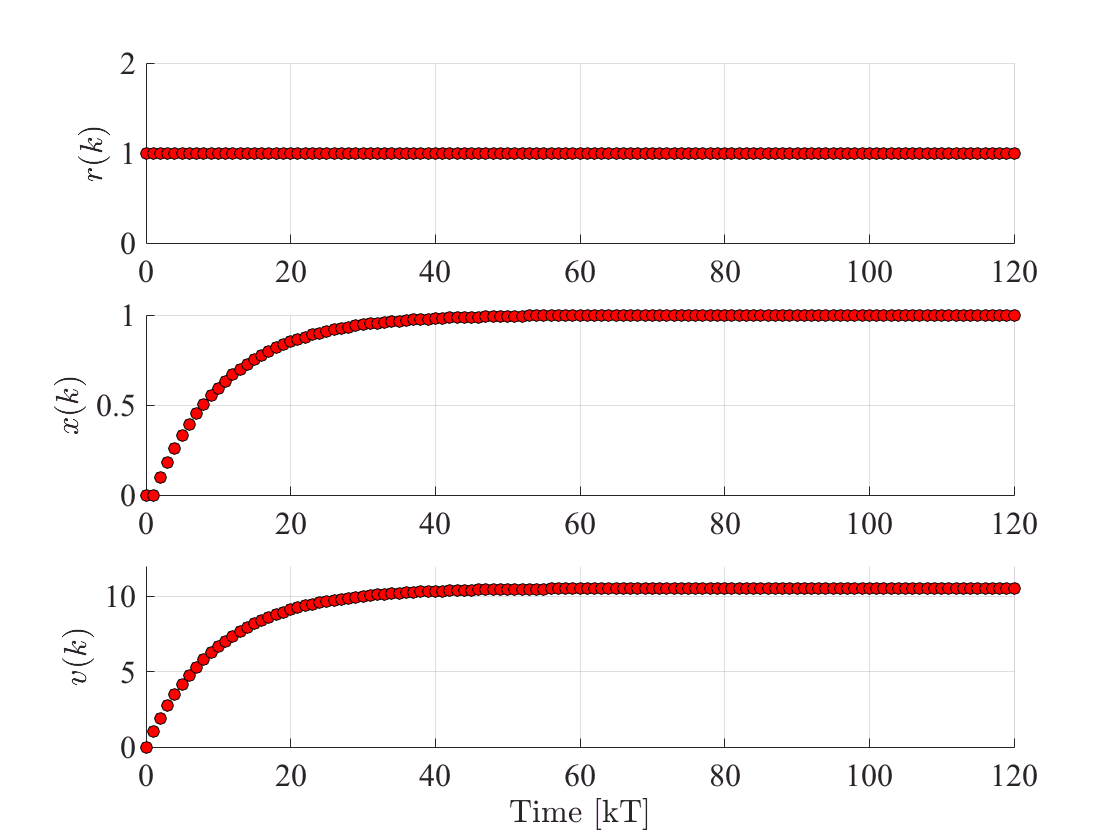

%% MODULE 14 - Problem 2 - An Integral Regulator for a Servo System
T = 0.1;

% Simulate the system in closed loop system with feedback gain k1, k2, 
% starting condition of x(0) = v(0) = 0 and constant reference r(k) = r = 1.');
k = 0:120;
r = ones(1,length(k));
x = zeros(2,length(k));
u = ones(1,length(k));
for i = 1:length(k)-1
    u(i) = -K*x(:,i);
    x(:,i+1) = F*x(:,i) + G*u(i) + Gr*r(i);
end
y = x(1,:);
v = x(2,:);

% Plotting
figure, h1 = subplot(3,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(k,r,'o','MarkerEdgeColor','k','MarkerFaceColor','r','MarkerSize',6);
ylabel('$r(k)$','FontName','times','FontSize',16,'Interpreter','latex')

h2 = subplot(3,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(k,y,'o','MarkerEdgeColor','k','MarkerFaceColor','r','MarkerSize',6);
ylabel('$x(k)$','FontName','times','FontSize',16,'Interpreter','latex')

h3 = subplot(3,1,3); set(h3,'FontName','times','FontSize',16)
hold on, grid on
plot(k,v,'o','MarkerEdgeColor','k','MarkerFaceColor','r','MarkerSize',6);
ylabel('$v(k)$','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [kT]','FontName','times','FontSize',16,'Interpreter','latex')
ylim([0 12]);

The steady state value $v(\infty) =\frac{u(\infty) + k_1x(\infty)}{k_2} = 10.5168$ also matches with the simulation (if run for long enough).

disp(['v_ss = ' num2str(v(end))])

v_ss = 10.5167
